## Solve a set of differential equations with the ODE45 algorythm

Made by [Slushee](https://slushee.dev/) (Pol Fernàndez Corella)

#### Initial conditions

initial_time = 1;   % Time of the initial conditions
end_time = 2;       % Time at which to calculate the solutions

x1_it = 0;          % Value of x_1 at the initial time
x2_it = 1;          % Value of x_2 at the initial time
x3_it = 2;          % Value of x_3 at the initial time

Define the set of differential equations at the end of the document [CLICK ME]

Calculate solutions:

initial_conditions = [x1_it; x2_it; x3_it];
time_span = [initial_time, end_time];

[t, X] = ode45(@equations, time_span, initial_conditions);
index_time = find(t == end_time);
X_time = X(index_time, :);

disp("Solutions = " + X_time(1) + ", " + X_time(2) + ", " + X_time(3))

Solutions = 1.4109, -1.1421, 10.7659


Graph the solutions:

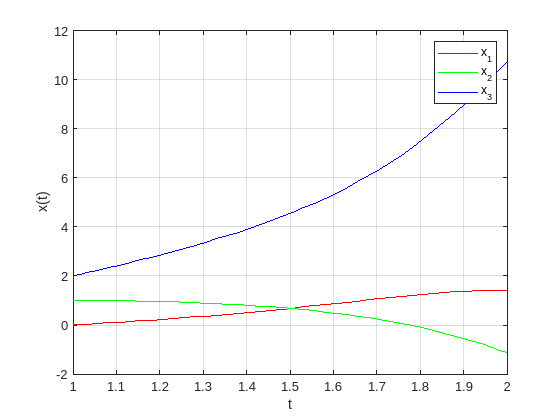

figure
plot(t, X(:, 1), 'r', t, X(:, 2), 'g', t, X(:, 3), 'b');
legend('x_1', 'x_2', 'x_3');
xlabel('t');
ylabel('x(t)');
grid on;

#### Definition of the differential equations

Write your set of equations with the following in mind:


$$\dot{x}_1 = dxdt(1) \ \ \ x_1 = x(1) \\
\dot{x}_2 = dxdt(1) \ \ \ x_2 = x(2) \\ 
\dot{x}_3 = dxdt(1) \ \ \ x_3 = x(3) \\$$


function dxdt = equations(t, x)
    dxdt = zeros(3, 1);
    dxdt(1) = x(2) * x(1)^2 + t;
    dxdt(2) = -x(3) + t * 2;
    dxdt(3) = x(3) * x(1) + 4;
end